# Lab 3

***REMINDER TO USE APPROPRIATE LABELS AND UNITS ON THE GRAPHS THIS WEEK!!!! HAVE LEGIT EXAMPLES WITH PREDETERMINED VARIABLE/THING WE MEASURE

#### *Asking a Statistical Question*

Task = <So in this lab we will assume that we know the form of the signal-free background distribution (determining a distribution from data will be next week's lab). In each of our three examples, your task will be to state the statistical question, convert it to math, then perform the associated analyses.>

## Problem 1: Temperature

____________________________________________________________________

In this example, we are looking at the temperature readings associated with some ambiguous experiment. The temperature should remain around 12 Kelvin for the experiment to run reliably, and the data we see tends to be consistently 12K within the 0.4 degree precision of the instruments. Essentially, our temperature distribution is a Gaussian centered at 12K with a standard deviation of 0.4. However, there are some occurrences where the thermal control system didn't work and the temperature was not near 12K. Additionally, there are various glitches in the thermometry which give anomalously high and low readings. Such data points should be identified and thrown out. ____________________________________________________________________

### A. Identifying and Removing "Bad" Data

#### EXPLORING APPROPRIATE PLOTS:

Temperature simulation of 100k "good" data points, with the addition of several "bad" data points:

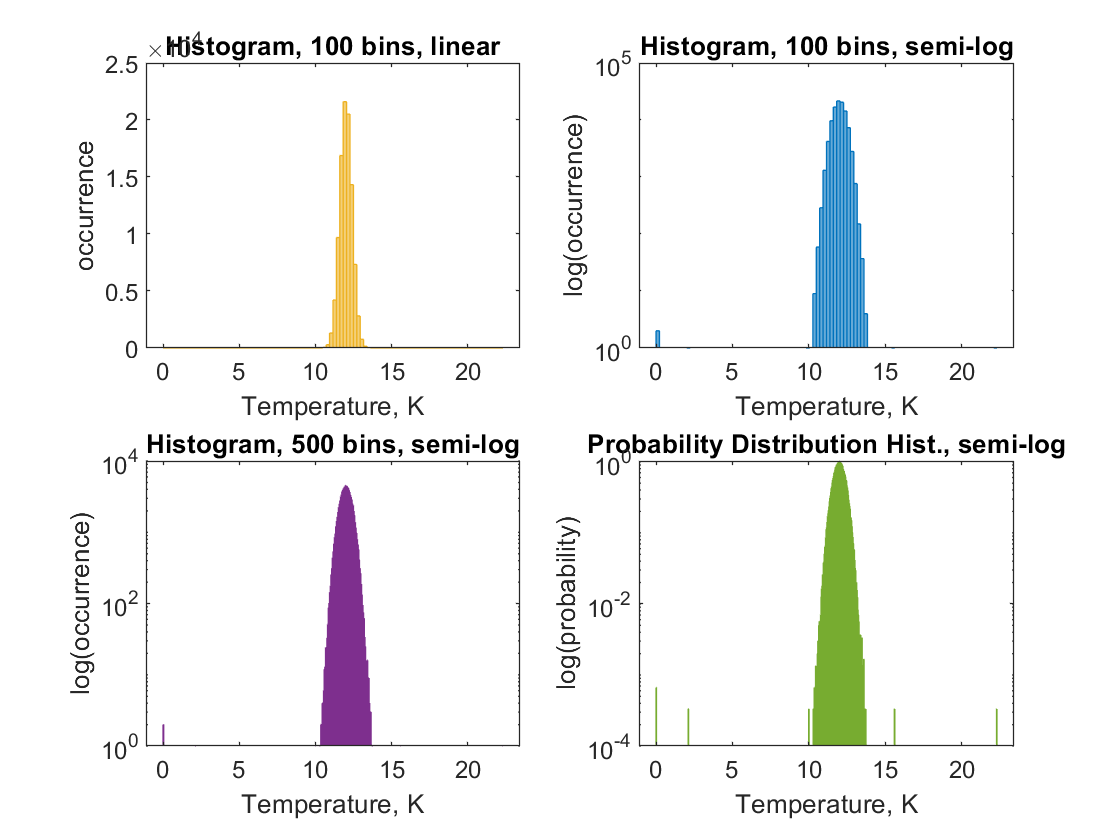

pd = makedist("Normal","mu",12,"sigma",0.4);
badpts = [10.,10.3,2.1,0.,0.,15.6,22.3,12.7];
dist = random(pd,1,100000);

d = [dist badpts];
x = linspace(4.95,5.05,1000);

subplot(2,2,1)
histogram(d,100,"FaceColor",'#EDB120',"EdgeColor",'#EDB120')
title('Histogram, 100 bins, linear')
xlabel('Temperature, K')
ylabel('occurrence')

subplot(2,2,2)
histogram(d,100,"Edgecolor",'#0072BD')
set(gca,'YScale','log')
title('Histogram, 100 bins, semi-log')
xlabel('Temperature, K')
ylabel('log(occurrence)')

subplot(2,2,3)
histogram(d,500,'Edgecolor','#7E2F8E')
set(gca,'YScale','log')
title('Histogram, 500 bins, semi-log')
xlabel('Temperature, K')
ylabel('log(occurrence)')

subplot(2,2,4)
histogram(d,'Normalization','pdf','Edgecolor','#77AC30')
set(gca,"YScale",'log')
title('Probability Distribution Hist., semi-log')
xlabel('Temperature, K')
ylabel('log(probability)')

#### THE STATISTICAL QUESTION:

<Insert Statistical Question clearly, in words, with excessive description of the question and why I chose it>

#### THE STATISTICAL QUESTION, IN MATH:

<Insert Statistical Question, in Math, with extreme clarity>

#### APPLICATION OF THE STATISTICAL QUESTION:

<explain how I'm applying my statistical question>

<create a truth table>

### B. On Omissions

<what is an omission>

<how does number of omissions depend on statistical threshold>

<is the number of omissions a predictable quantity?>

### C. Mistakes of Commission

<What are mistakes of commission>

<does my algorithm have mocs?>

<are they avoidable?>

<how do they depend on my threshold?>

***Notes on problem 1:***

given a data point, what is the probability that it would be explained by the background? (APPLIED TO EVERY POINT)

-- write an algorithm to differentiate between good and bad data points; compare various methods + truth tables to see which is the best for the purpose of this question. 

-- determine sigma of point and if it's below some threshold then assign it as a "bad" data point. 

A) So our goal is to identify bad data and throw it out.

- Start by exploring the data you have created with appropriate plots

- State the statistical question in words. Be very clear, and describe why you have chosen this statistical question.

- Restate your question in math. Be very clear.

- Apply your statistical test and construct a truth table.

The idea is how often you kept the known good data (True T & Your Test Good), how often you correctly discarded bad data (Bad T & Your Test Bad), and how often mistakes were made of either omission or commission (off diagonals).

B) How does the number of omissions, where you threw out good data, depend on the statistical threshold you chose and is it a predictable quantity?

C) Are there mistakes of commission (bad data getting in)? If yes, are they avoidable and how do they depend on your statistical threshold?

## Problem 2: Asteroids

In this example we will be looking for asteroids. If we look at the alignment of stars on subsequent images, they don't perfectly align due to atmospheric and instrumental effects (even ignoring proper motion). The resulting distribution is two dimensional, and for this lab let's assume it is a 2D Gaussian with 1 arcsecond RMS.

sample graphical representation:

`a ``=` `np``.``vstack``((``stats``.``norm``.``rvs``(` `scale` `=` `1``,` `size` `=` `100000``),` `stats``.``norm``.``rvs``(` `scale` `=` `1``,` `size` `=` `100000``)))``a``.``shape``fig``,` `ax` `=` `plt``.``subplots``(``1``,` `1``)``h` `=` `ax``.``hist2d``(``a``[``0``,:],``a``[``1``,:],``bins``=``100``,` `density``=``True``);``ax``.``set_aspect``(``'equal'``,` `'box'``)``plt``.``xlim``([``-``3` `,` `3``])``plt``.``ylim``([``-``3` `,` `3``])``plt``.``title``(``"2D Histogram of positional uncertainty"``,` `fontsize` `=` `24``)``plt``.``ylabel``(``"$\Delta$y arcseconds"``,` `fontsize` `=` `18``)``plt``.``xlabel``(``"$\Delta$x arcseconds"``,` `fontsize` `=` `18``)``plt``.``colorbar``(``h``[``3``],` `ax``=``ax``)`

If I have a potential asteroid, it will have some true movement between the images. We would like a '5 sigma' detection of movement. What is that distance in arcseconds?

- What is the question in words?

- What is the question in math? [Hint: Come up with an analytic description of your pdf(). The Blue Book may be helpful here.]

- What distance in arcseconds represents a 5 sigma detection of motion?

## Problem 3: Cosmic Rays

As we discussed in class, one of the key backgrounds for gamma-ray telescopes are cosmic rays. Cosmic rays are charged particles—usually protons or electrons but can include atomic nuclei such a alpha particles (helium) or iron. Because of their charge cosmic rays spiral in the magnetic field of the galaxy. From the perspective of the Earth they appear to be coming uniformly from all directions like a high energy gas, and the direction the cosmic ray is travelling when it reaches the Earth tells us nothing about where it came from because we don't know what tortured path it has taken through the galaxy to reach us. However, at trillion electron volt energies and above, the spiral loops are fairly big and the sun and the moon will block cosmic rays. This means the sun and the moon appear as holes in the cosmic ray sky (cosmic rays from that direction are absorbed).

Assume in a moon sized patch on the sky we normally have a cosmic ray rate of 1 cosmic ray per minute (arrivals are random in time). If we can observe where the moon is for 8 hours per night (not too close to the horizon) and we observe for 15 days and see 6800 cosmic rays, what is the signficance of our moon shadow detection?

- background  = poisson, 1 ray/min

- convolution, 8 hours/day; 15 days

                summation, X1+X2+...+Xn --> (OR) (not inc. AND subtraction)

                see page 98-99 of notebook for process :)

- see 6800 cosmic rays

- find significance

As always:

- What is the question in words?

- Translate the question to math, describing both the expected background pdf() and the integral you need to do.

- Convert to sigma.

There are some unique aspects to this problem. Make sure you explore them in your explanation.